# ME5704 Robotics and Automation

# Final Project - Q3

name : Joshua Hoegerman

date : 12/11/2022

How to run the code:

It should be able to run as is if you press run, but if you have already ran through some it, its broken into parts so you dont have to repeatedly run the computationally diffiucult parts.

Starts with base initialization as done prior. New changes are shown in difference in ODE construction and closed loop dyn function with different input integration. See equations in relevant sections.

## House Cleaning

clc
clear all
clf
sympref('FloatingPointOutput',true);

## Initialization

%DH Conventions from given github
syms q1 q2 q3 q4 q5 q6 qd1 qd2 qd3 qd4 qd5 qd6

%How many of hte robot arms links are being considered
links = 4;


%robot length params
D1 = .2755;
D2 = .41;
D3 = .2073;
D4 = .0743;
D5 = .0743;
D6 = .1687;
e2 = .0098;
%Alternate parameters
aa = 11.0*pi / 72;
ca = cos(aa);
sa = sin(aa);
c2a = cos(2*aa);
s2a = sin(2*aa);
d4b = (D3)+((sa/s2a)*D4);
d5b = (((sa/s2a)*D4)+((sa/s2a)*D5));
d6b = ((sa/s2a)*D5)+D6;

% DH vectors

alpha = [pi/2;pi;pi/2;2*aa;2*aa;pi];

ai1 = [0;D2;0;0;0;0];
di = [D1;0;e2;-d4b;-d5b;-d6b];

%classic DH frame
% q1 = 0;
% q2 = 0;
% q3 = 0;
% q4 = 0;
% q5 = 0;
% q6 = 0;
% A poorly worded frame choice that messed me up for a long while
% q1 = 180*(pi/180);
% q2 = 270*(pi/180);
% q3 = 90*(pi/180);
% q4 = 180*(pi/180);
% q5 = 180*(pi/180);
% q6 = 350*(pi/180);
% full extension y
% q1 = 1.5*pi;
% q2 = pi;
% q3 = 1.5*pi;
% q4 = pi/2;
% q5 = 1.0*pi;
% q6 = 0;


%starting configuration
%q0 = ([0,0,0,0,0,0]').*(pi/180);
%q0 = ([1.5*pi,pi,3*pi/2,.5*pi,1.0*pi,0]);
%(pi,3*pi/2,pi/2,pi,pi,350*pi/180)
q = [q1;q2;q3;q4;q5;q6];
dq = [qd1;qd2;qd3;qd4;qd5;qd6];
q0 = ([1.5*pi,pi,3*pi/2,.5*pi,1.0*pi,0])';
q0 = q0*(.95 + (rand/10)) %varies q0 by up +- 5  percent

q0 =     4.8607
    3.2405
    4.8607
    1.6202
    3.2405
         0


mM = [.63,.64,.64,.64,.64,.39,.39,.39,.93];


## T Matricies and a lot of unused fluff

This part of the code just runs through a DH convention based calculation of the T matricies to get hte variable positions and Rotation matricies for the joints.



A_01= eye(4,4);


for i = 1:length(q)-5

    %temp = dh_move(alpha(i),theta1(i),di(i),ai1(i))
    A_01 =   A_01*dh_move(alpha(i),q(i),di(i),ai1(i));
end
%02

A_02= eye(4,4);

for i = 1:length(q)-4

    %temp = dh_move(alpha(i),theta1(i),di(i),ai1(i))
    A_02 = A_02*dh_move(alpha(i),q(i),di(i),ai1(i));
end
%03

A_03= eye(4,4);

for i = 1:length(q)-3

    %temp = dh_move(alpha(i),theta1(i),di(i),ai1(i))
    A_03 = A_03*dh_move(alpha(i),q(i),di(i),ai1(i));
end
%04

A_04= eye(4,4);

for i = 1:length(q)-2

    %temp = dh_move(alpha(i),theta1(i),di(i),ai1(i))
    A_04 = A_04*dh_move(alpha(i),q(i),di(i),ai1(i));
end
%05

A_05= eye(4,4);

for i = 1:length(q)-1

    %temp = dh_move(alpha(i),theta1(i),di(i),ai1(i))
    A_05 = A_05*dh_move(alpha(i),q(i),di(i),ai1(i));
end
%06
A_06= eye(4,4);

for i = 1:length(q)

    %temp = dh_move(alpha(i),theta1(i),di(i),ai1(i))
    A_06 = A_06*dh_move(alpha(i),q(i),di(i),ai1(i));
end

concetrated = [A_01;A_02;A_03;A_04;A_05;A_06];




P = [];

for i = 1:6
    use = concetrated( ((4*(i-1))+1:(4*(i-1))+3),:);
    dte = use(1:3,4);
    P = [P,dte];
end

%finding jacobian products
% os =[0;0;0];
% z00 = [0;0;1];
% %zs = [z00,z00,];
% 
% for i = 1:length(theta1)
%     otemp = concetrated( ((4*(i-1))+1:(4*(i-1))+3),(4));
%     os = [os,otemp];
%     
%     Rtemp = concetrated( ((4*(i-1))+1:(4*(i-1))+3),(1:3) );
%     %ztemp = Rtemp*z00;
%     
% end
% n =length(os);
% %translating into each half of the normal Jacobian
% Jv = [];
% Jw = [];
% Jinv = [];
% for i = 1:n-1
%    Jvn = (cross(z00,(os(:,n) - os(:,i))));
%    Jwn = z00;
%    %Jwn = zs(i);
%    Jw = [Jw,Jwn];
%    Jv = [Jv, Jvn];
% %    Jin = J_inverse(Jvn);
% %    Jinv = [Jin; Jinv];
% end
% oo_ee = d(1:3,end);
% Jv2 = jacobian(oo_ee,[q1,q2,q3,q4,q5,q6]);
%printPosArm(A_01,A_02,A_03,A_04,A_05,A_06)


%Final Jacobian
%J = [Jw;Jv];





##  D,C, and G

Here is where i am finding the D C and G vectors for the later lagrangian.

 For the inertial matrix, I'm just following the usual math convention with the differentiation of position to find the releveant Jv for the Jacobian and a constant DH convention set for Jw. For the inertial tensor, I'm assuming all links are symmetrical cylinders with uniform mass distribution to simplify calculations. 

For the Corialis matrix, I'm just using the standard mathmatical basis for the differentiation of the mass- inertia matrix.

Gravitational is simply just taking the gradient of the potential energy due to gravity with respect to each angular joint


%Body variables
L = [D1;D2;-e2;d4b;d5b;d6b]; %length of assuming perfectly cylindrical joints
%assuming each link has an equal radius across all joints of 5 cm or .05
% and assuming all joints have symmetric weight distribution

%this makes both x and y = r where r is constant of .05m and L being a
%variable distance relative to each link
%Where the formula for each I (im assuming equivalent geometry because you
%didnt give us enough information to care further)
%Ixx,Iyy = ( (1/12)*M*h^2 ) + ( .25*M*r^2 )
%Izz = .5*M*r^2
r = .05; %radius of links (m)
%mM = [.63,.64,.64,.64,.64,.39,.39,.39,.93];


%D mat
D = 0;
for i = 1:links
    Jv1 = [];
    Jw1 = [];
    for use = 1:links
        Jvuse = diff(P(:,i),q(use));
        Jv1 = [Jv1,Jvuse]; 
    end
    
    for use2 = 1:i
        Jw1 = [Jw1,[0;0;1]];
    end
    Jw1 = [Jw1,zeros(3,links-i)];
    
    R1 = concetrated( ((4*(i-1))+1:(4*(i-1))+3),1:3); %concentrated is the particular T matrix
    m1 = mM(i);
    
    Ixxyy = ( (1/12)*m1*(L(i)^2) ) + ( .25*m1*r^2 );
    Izz = .5*m1*r^2;
    I1 = [Ixxyy,0,0;        0,Ixxyy,0;        0,0,Izz];
    D_i = m1*(Jv1'*Jv1)+(Jw1'*R1*I1*R1'*Jw1);
    D = D + D_i;


end
%cmat ijk 
cmat = [0,0,0,0;0,0,q1,0;0,0,0,0;0,0,0,0]; %have to do it this way bc of arry typecasting
for k = 1:links
    for j = 1:links
        cijk = 0;
        for i1 = 1:links
            cijk = cijk+.5*(  ( ( diff(D(k,j),q(i))+diff(D(k,i),q(j))-diff( D(i,j),q(i) ) ) *dq(i) ) );
        end
        cmat(k,j) = simplify(cijk);
    end
end
%g mat

%sum of PE
P_G = 0;
for i = 1:links
   P_G = P_G + P(3,i) * mM(i)*9.81; %where P(3,i) is z coor of each joint, g= 9.81m/s2
end
g1 =[];
for use = 1:links
    guse = diff(P_G,q(use));
    g1 = [g1;guse]; 
end
cmatdq = cmat*dq(1:links);

mat_jacob = Jv1;


## Function and C mex generation

Making functions, see files and prior calculations for more details

matlabFunction(D, 'vars', {q(1:links)}, 'file', 'inertia_Matrix', 'Optimize', false);
matlabFunction(cmatdq, 'vars', {q(1:links),dq(1:links)}, 'file', 'Coriolis_centrifugal_terms', 'Optimize', false);
matlabFunction(cmat, 'vars', {q(1:links),dq(1:links)}, 'file','Coriolis_pure_terms' , 'Optimize', false);
matlabFunction(g1, 'vars', {q(1:links)}, 'file', 'gravity_terms', 'Optimize', false);
matlabFunction(P(:,1:links), 'vars', {q(1:links)}, 'file', 'forward_kinematics', 'Optimize', false);
matlabFunction(mat_jacob, 'vars', {q(1:links)}, 'file', 'Jacobian', 'Optimize', false);
% matlabFunction(u, 'vars', {q(1:links),dq(1:links),t}, 'file', 'input_matrix', 'Optimize', false);

codegen inertia_Matrix -args {zeros(4,1)}  -o Cfcn_inertia_Matrix -report

Code generation successful: View report



codegen Coriolis_pure_terms -args {zeros(4,1),zeros(4,1)}  -o Cfcn_Coriolis_pure_terms

Code generation successful.



codegen Coriolis_centrifugal_terms -args {zeros(4,1),zeros(4,1)}  -o Cfcn_Coriolis_centrifugal_terms

Code generation successful.



codegen gravity_terms  -args {zeros(4,1)}  -o Cfcn_gravity_terms  -report

Code generation successful: View report



codegen forward_kinematics      -args {zeros(4,1)} -o Cfcn_forward_kinematics      -report

Code generation successful: View report



codegen Jacobian      -args {zeros(4,1)} -o Cfcn_Jacobian      -report

Code generation successful: View report



## Question 1&3 : Using ODE and Finding Resultant Robot Movement

Using ode to take numerical diffentials to find q and dq for resulting robot movement over timespan [0,20]

Time        = [];
X           = [];
Q           = [];
dQ          = [];



q0d = q0(1:links); %q0 = q0*(.5 + (rand/2)) %varies joint positions for desired start by up +- 25  percent

qd = zeros(links,1);
for i = 1:links
    qd(i) = ( ( rand-.5 )/100 ) ; %each joint has a random velocity from -.005 to + .005 rad/s from base initial of 0.
end
xfunc_use = [q0d;qd;zeros(3,1)];
T_span = [0,20];
% npoints = 10000;
% T_span2 = [T_span(1):(T_span(2)/npoints):T_span(2)];

[t,x]   = ode15s( @closed_loop_dyn,T_span,xfunc_use );

% Save data
t_temp  = t;
x_temp  = x;

q       = x(:,1:links);  % Position
dq      = x(:, links+1:(2*links) );% Velocity
fdhat = x(:, (2*links)+1:end ); 
[n,~]   = size(q);

P1 = zeros(3,n);
P2 = zeros(3,n);
P3 = zeros(3,n);
P4 = zeros(3,n);
P5 = zeros(3,n);
P6 = zeros(3,n);
for uset = 1:n
    pout = Cfcn_forward_kinematics(q(uset,1:links)');
    P1(:,uset) =  pout(:,1);
    P2(:,uset) =  pout(:,2);
    P3(:,uset) =  pout(:,3);
    P4(:,uset) =  pout(:,4);    
%     P5(:,uset) =  pout(:,5);
%     P6(:,uset) =  pout(:,6);
end

q(end,:)

ans =     0.0058    0.0049    0.0057    0.0060


sum(abs(q(end,:))) % Since qdes for end is 0, this shows end error for testing gain values

ans = 0.0225

%honestly, base K1 = diag([1,1,1]) worked pretty well. Messed with it and
%it got a little better but not by much.


## Question 4: Plotting q and d/dq

Self explanatory Figure 2 is q [Angular position] vs time, figure 3 is d/dq [angular velocity] vs time, figure 4 is the tracked force error

In zip file as figure 2 and 3.

%alpha for bezier
q0 = ([1.5*pi,pi,3*pi/2,.5*pi,1.0*pi,0])'; %desired start joint vals not real 
q0a = q0(1:links); 
qfin = zeros(links,1); %desired start vels not real
%     vf = zeros(1,links);
%     vi = zeros(1,links);
M = 3;

alphamat = [zeros(4,4)];

    for i = 1:4
        diff = (qfin(i) - q0a(i)) / (M);
        alphamat(i,:) = (q0a(i):diff:qfin(i)) ;
    end
[K_D,A_PD,theta] = PC_J2_gains;

qhat_mat = zeros(size(q));
qdhat_mat = zeros(size(dq));
f_mat = zeros(length(dq),3);
freal = zeros(length(dq),3);
f = zeros(3,1);
T_use = [T_span(1):length(dq):T_span(2)];

T_use = 0

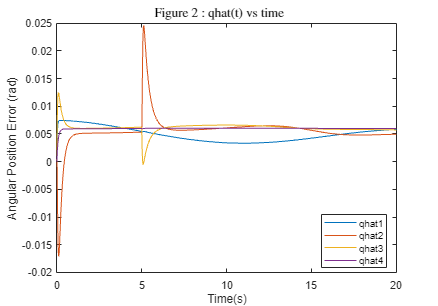

for i = 1:length(dq)
    
    J   = Cfcn_Jacobian(q(i,:)');
    
    %u = input_matrix(alphamat,t/20,A_PD,K_D,q,dq,D,C,G);
    %manual (non-function) form input matrix function
    s = t(i)/T_span(2);
    qd = bezier( alphamat,s);
    d_qd = beziera(alphamat,s);
    d2_qd = bezierd(alphamat,s);

    qhat = ( q(i,:)'-qd );
    qhat_mat(i,:) = qhat';
    dqhat = ( dq(i,:)' - d_qd );
    qdhat_mat(i,:) = dqhat';

    zet = d_qd - (A_PD*(qhat));
    d_zet = d2_qd - A_PD*(dqhat);
    sigma = dqhat + (A_PD*qhat);

    fhat = theta*J*sigma;
    
    if t>5
        if t>10
            m=10;
        else
            m = 5;
        end
    else
        m = 2;
    end
    g0 = -9.81; %(m/s2)
    fuse = [0;0;m*g0];
    freal(i,:) = fuse;
    f_mat(i,:) = f'; %torque
    f = fhat;
end




%



clf('reset')
figtitle = append("Figure 2 : qhat(t) vs time");
figname = figure('Name',figtitle,'Units', "centimeters", 'Position', [0.1 0.1 100 70]);
for i = 1:links
    plot(t,qhat_mat(:,i))
    hold on 
end
sgtitle(figname,figtitle, 'interpreter', 'latex')
legend("qhat1","qhat2","qhat3","qhat4",'location','best')
xlabel("Time(s)")
ylabel("Angular Position Error (rad)")

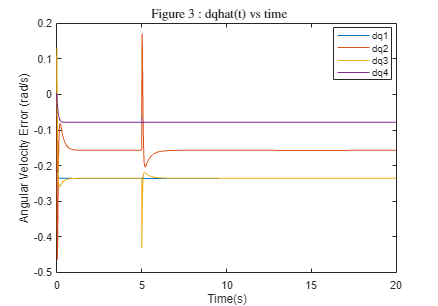



%
clf('reset')
figtitle = append("Figure 3 : dqhat(t) vs time");
figname = figure('Name',figtitle,'Units', "centimeters", 'Position', [0.1 0.1 100 70]);
for i = 1:links
    plot(t,qdhat_mat(:,i))
    hold on 
end
sgtitle(figname,figtitle, 'interpreter', 'latex')
xlabel("Time(s)")
ylabel("Angular Velocity Error (rad/s)")
legend("dq1","dq2","dq3","dq4",'location','best')

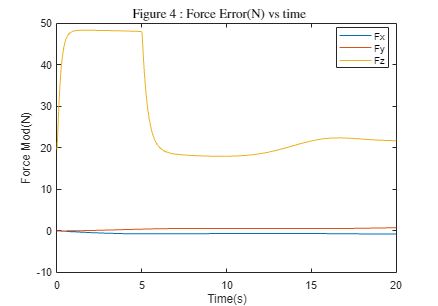


f_tild = fdhat;
f_tild(:) = fdhat(:) -  freal(:);
%
clf('reset')
figtitle = append("Figure 4 : Force Error(N) vs time");
figname = figure('Name',figtitle,'Units', "centimeters", 'Position', [0.1 0.1 100 70]);
for i = 1:3
    plot(t,( f_tild(:,i) ))
    hold on 
end
sgtitle(figname,figtitle, 'interpreter', 'latex')
xlabel("Time(s)")
ylabel("Force Mod(N)")
legend("Fx","Fy","Fz",'location','best')

clf

## Question 4:Robot animation (see function below or in file for more detail)

Current Settings:

MAKE_FILM : Boolean if you want to save resulting plot as an mp4. [Currently: 1, YES DO SAVE]

shadowing: Details how many steps you want shown in movement. If on decreases amount of steps by a factor of 10. [Current = Off]

slow_motion :pauses between movement steps to slow robot's movement as visible to the user [Current = On]

P1-P4 (P1-P6): Position log of robots movements through prior found ode.

%animate_robot_move(MAKE_FILM,shadowing,slow_motion,P1,P2,P3,P4)
%animate_robot_move(1,1,1,P1,P2,P3,P4)
% mp4 saved as 'jazz_swingin_verQ3_adap'

function [dx]= closed_loop_dyn(t,x)
    links = 4;
    % State decomposition.
    q  = x(1:links);
    dq = x( links+1:(2*links) );
    fhat = x( (2*links)+1:end );
    %alpha for bezier
    q0 = ([1.5*pi,pi,3*pi/2,.5*pi,1.0*pi,0])'; %desired start joint vals not real 
    q0a = q0(1:links); 
    qfin = zeros(links,1); %desired start vels not real
%     vf = zeros(1,links);
%     vi = zeros(1,links);
    M = 3;
    
    alphamat = zeros(4,4);
    for i = 1:4
        diff = (qfin(i) - q0a(i)) / (M);
        alphamat(i,:) = (q0a(i):diff:qfin(i)) ;
    end

    % Dynamic terms
    D   = Cfcn_inertia_Matrix(q);
    Cdq = Cfcn_Coriolis_centrifugal_terms(q,dq);
    C = Cfcn_Coriolis_pure_terms(q,dq);
    G   = Cfcn_gravity_terms(q);
    
    J = Cfcn_Jacobian(q);
    [adapt,u] = input_matrix2(alphamat,t/20,q,dq,D,C,G,J,fhat );
    
    %adding point mass
    %m = 3; %(kg)
    % if t>5
    %     if t>10
    %         m=10;
    %     else
    %         m = 5;
    %     end
    % else
    %     m = 2;
    % end
    if t>5
        m = 0;
    else
        m = 3;
    end
    g0 = 9.81; %(m/s2)
    f = [0;0;m*g0];
    H   = Cdq + G;   
    % Closed-loop vector filed
    fcl = [dq; inv(D)*(  u-H+( (J')*f)  )  ;adapt];
    dx  = fcl;
end

%
function [adapt,u] = input_matrix2(alphamat,s,q,dq,D,C,G,J,fhat)
    %for input s time, A_PD, K_D,q,dq,D,C,G.
    %Output : u
    [K_D,A_PD,theta] = PC_J2_gains;

    qd = bezier( alphamat,s);
    d_qd = beziera(alphamat,s);
    d2_qd = bezierd(alphamat,s);
    
    qhat = q-qd;
    
    dqhat = dq - d_qd;
    
    
    zet = d_qd - (A_PD*(qhat));
    d_zet = d2_qd - A_PD*(dqhat);
    sigma = dqhat + (A_PD*qhat);
    
%    dist =
    u = (D*d_zet)+ (C*zet) + (G) - (K_D*sigma) - ( (J')*fhat); %keeping d and G formal sepearte 
    adapt = theta*J*sigma;
%     D   = Cfcn_inertia_Matrix(q);
%     Cdq = Cfcn_Coriolis_centrifugal_terms(q,dq);
%     G   = Cfcn_gravity_terms(q);
end


function A = dh_move(alpha,theta,d,a)
    A = [];
    for i =1:length(theta)
        %Rth_alpha = [cos(theta(i)), (-sin(theta(i))*cos(alpha(i))),sin(theta(i))*sin(alpha(i)),0;
            %sin(theta(i)),cos(theta(i))*cos(alpha(i)),-cos(theta(i))*sin(alpha(i)),0;
            %0,sin(alpha(i)),cos(alpha(i)),0;
            %0,0,0,1];
        R_alphax = [ 1 0 0 0; 0, cos(alpha(i)),-sin(alpha(i)),0; 0, sin(alpha(i)), cos(alpha(i)),0; 0,0,0,1];
        R_thetaz = [cos(theta(i)), - sin(theta(i)), 0,0;sin(theta(i)),cos(theta(i)),0,0;0,0,1,0;0,0,0,1];
        T_dz = [1,0,0,0;0,1,0,0;0,0,1,d(i);0,0,0,1];
        
        T_ax = [1,0,0,a(i);0,1,0,0;0,0,1,0;0,0,0,1];

        A1 = R_thetaz*T_dz*T_ax*R_alphax;
        A = [A; A1];
    end

end




%animation function
function animate_robot_move(MAKE_FILM,shadowing,slow_motion,P1,P2,P3,P4)
    %name and set file
    avifile_name = 'jazz_swingin_verQ3_adap';
    h = figure('Name',avifile_name);%,'Position',[400 200 800 680]);
    set(h,'Renderer','zbuffer')
    %save
    if(MAKE_FILM)
        mov = VideoWriter([avifile_name]); %,'MPEG-4');
        %mov.FrameRate = 30; % Real time animation
        open(mov);
    end % end of if
    
    if shadowing
        temp = 10;
    else
        temp = 1;
    end % end of if
    

    [~,n] = size(P2);
    npoints = 50;
    for i=1:temp:n
        
        %pause
        %q   = Q(:,i);
        %assign linear positions for each joint with dx,y,z being the
        %linspaced link between each
        p0 = [0;0;0];
        x0 = p0(1);
        y0 = p0(2);
        z0 = p0(3);

        p1  = P1(:,i);
        x1 = p1(1);
        y1 = p1(2);
        z1 = p1(3);
        dx1 = linspace(x0,x1,npoints);
        dy1 = linspace(y0,y1,npoints);
        dz1 = linspace(z0,z1,npoints);

        p2  = P2(:,i);
        x2 = p2(1);
        y2 = p2(2);
        z2 = p2(3);
        dx2 = linspace(x1,x2,npoints);
        dy2 = linspace(y1,y2,npoints);
        dz2 = linspace(z1,z2,npoints);

        p3  = P3(:,i);
        x3 = p3(1);
        y3 = p3(2);
        z3 = p3(3);
        dx3 = linspace(x2,x3,npoints);
        dy3 = linspace(y2,y3,npoints);
        dz3 = linspace(z2,z3,npoints);

        p4  = P4(:,i);
        x4 = p4(1);
        y4 = p4(2);
        z4 = p4(3);
        dx4 = linspace(x3,x4,npoints);
        dy4 = linspace(y3,y4,npoints);
        dz4 = linspace(z3,z4,npoints);

%         p5  = P5(:,i);
%         x5 = p5(1);
%         y5 = p5(2);
%         z5 = p5(3);
%         dx5 = linspace(x4,x5,npoints);
%         dy5 = linspace(y4,y5,npoints);
%         dz5 = linspace(z4,z5,npoints);
% 
%         p6  = P6(:,i);
%         x6 = p6(1);
%         y6 = p6(2);
%         z6 = p6(3);
%         dx6 = linspace(x5,x6,npoints);
%         dy6 = linspace(y5,y6,npoints);
%         dz6 = linspace(z5,z6,npoints);
        
        
        clf;
        %axis off
        %plotting links from dxyz
        plot3(dx1,dy1,dz1)
        hold on
        plot3(x0,y0,z0,'o')
        hold on
        plot3(x1,y1,z1,'o')
        hold on
        plot3(dx2,dy2,dz2)
        hold on
        plot3(x2,y2,z2,'o')
        hold on
        plot3(dx3,dy3,dz3)
        hold on
        plot3(x3,y3,z3,'o')
        hold on
        plot3(dx4,dy4,dz4)
        hold on
        plot3(x4,y4,z4,'o')
        hold on
%         plot3(dx5,dy5,dz5)
%         hold on
%         plot3(x5,y5,z5,'o')
%         hold on
%         plot3(dx6,dy6,dz6)
%         hold on
%         plot3(x6,y6,z6,'o')


        
%       workspace limits
        xlim([-.75 .75])
        ylim([-.75 .75])
        zlim([-.75 .75])
        title("Robot animation")
        xlabel("x_Axis (m)")
        ylabel("y_Axis (m)")
        zlabel("z_Axis (m)")
        if(MAKE_FILM)
            F = getframe(gcf);
            %F = im2frame(gcf);
            writeVideo(mov,F);
            %F = getframe(gcf);
            %mov = addframe(mov,gcf);
        end % end of if
        drawnow;
        
        switch slow_motion
            case 1
                pause(1);
            otherwise
        end
    
    end
    
    % Close AVI file.
    if(MAKE_FILM)
        close(mov);
    end
    % end of if(.)

end

function printPosArm(T1,T2,T3,T4,T5,T6)
%         p1 = T1(1:3,4);
%         p2 = T2(1:3,4);
%         p3 = T3(1:3,4);
%         p4 = T4(1:3,4);
%         p5 = T5(1:3,4);
%         p6 = T6(1:3,4);
        p1 = T1;
        p2 = T2;
        p3 = T3;
        p4 = T4;
        p5 = T5;
        p6 = T6;
        npoints = 50;
        p0 = [0;0;0];
        x0 = p0(1);
        y0 = p0(2);
        z0 = p0(3);

        
        x1 = p1(1);
        y1 = p1(2);
        z1 = p1(3);
        dx1 = linspace(x0,x1,npoints);
        dy1 = linspace(y0,y1,npoints);
        dz1 = linspace(z0,z1,npoints);

        
        x2 = p2(1);
        y2 = p2(2);
        z2 = p2(3);
        dx2 = linspace(x1,x2,npoints);
        dy2 = linspace(y1,y2,npoints);
        dz2 = linspace(z1,z2,npoints);

        
        x3 = p3(1);
        y3 = p3(2);
        z3 = p3(3);
        dx3 = linspace(x2,x3,npoints);
        dy3 = linspace(y2,y3,npoints);
        dz3 = linspace(z2,z3,npoints);

        
        x4 = p4(1);
        y4 = p4(2);
        z4 = p4(3);
        dx4 = linspace(x3,x4,npoints);
        dy4 = linspace(y3,y4,npoints);
        dz4 = linspace(z3,z4,npoints);

        
        x5 = p5(1);
        y5 = p5(2);
        z5 = p5(3);
        dx5 = linspace(x4,x5,npoints);
        dy5 = linspace(y4,y5,npoints);
        dz5 = linspace(z4,z5,npoints);

        
        x6 = p6(1);
        y6 = p6(2);
        z6 = p6(3);
        dx6 = linspace(x5,x6,npoints);
        dy6 = linspace(y5,y6,npoints);
        dz6 = linspace(z5,z6,npoints);
        
        
        clf;
        %axis off
        %plotting links from dxyz
        plot3(dx1,dy1,dz1)
        hold on
        plot3(x0,y0,z0,'o')
        hold on
        plot3(x1,y1,z1,'o')
        hold on
        plot3(dx2,dy2,dz2)
        hold on
        plot3(x2,y2,z2,'o')
        hold on
        plot3(dx3,dy3,dz3)
        hold on
        plot3(x3,y3,z3,'o')
        hold on
        plot3(dx4,dy4,dz4)
        hold on
        plot3(x4,y4,z4,'o')
        hold on
        plot3(dx5,dy5,dz5)
        hold on
        plot3(x5,y5,z5,'o')
        hold on
        plot3(dx6,dy6,dz6)
        hold on
        plot3(x6,y6,z6,'o')
%         xlim([-.75 .75])
%         ylim([-.75 .75])
%         zlim([-.75 .75])
end